# 1.1


syms x2dot x4dot x1 x2 x3 x4 u

x1dot = x2;
x3dot = x4;
% Define the equations
eq1 = ((0.27 + 4.32*10^(-5)/0.0004))*x2dot + ((0.27*0.0004 + 4.32*10^(-5)))*x4dot/0.02 - 0.27*x1*x4^2 == (0.27*9.81*sin(x3));
eq2 = (0.27*(x1)^2 + 4.32*10^(-5) + 14.025*10^(-2))*x4dot + (2*0.27*x2*x1 + (0.49)^2)*x4 + (10^(-3) *(0.49)^2)*x3 +  ((0.27*0.0004 + 4.32*10^(-5)))*x2dot/0.02 -(0.27*9.81*x1*cos(x3)) == u*(0.49*cos(x3));

% Solve the equations for x and y
sol = solve([eq1, eq2], [x2dot, x4dot]);

% Extract the separate equations for x and y
eq_x2dot = sol.x2dot;
eq_x4dot = sol.x4dot;

% Display the resulting equations
disp("x1dot:");

x1dot:


disp(x2);

$$x_{2}$$


disp("x2dot:");

x2dot:


disp(eq_x2dot);

$$\frac{71778311772385457136805581255138607104000\,{x_{1}}^{3}\,{x_{4}}^{2}+704145238487101334512062752112909735690240\,\sin\left(x_{3}\right)\,{x_{1}}^{2}+37296329811650471908024340234577431756800\,x_{1}\,{x_{4}}^{2}+4019585459253586025753230536867840000000\,x_{2}\,x_{1}\,x_{4}-19716066677638839456319595783336755200000\,\cos\left(x_{3}\right)\,x_{1}+1787226794012566675524723429448089600000\,x_{4}+1787226794012566537115851165353515625\,x_{3}+365876995452291129417718777701204605534208\,\sin\left(x_{3}\right)-3647401620433809541887190672343040000000\,u\,\cos\left(x_{3}\right)}{5\,\left(20097927296267927998305562751438809989120\,{x_{1}}^{2}+10431717507976222092181648289816026595029\right)}$$


disp("x3dot:");

x3dot:


disp(x4);

$$x_{4}$$


disp("x4dot:");

x4dot:


disp(eq_x4dot);

$$-\frac{1152921504606846976\,\left(77508606911709102500\,x_{3}+77508606911709108502528\,x_{4}+17100961859812073090625\,\sin\left(x_{3}\right)+1743217314965552812500\,x_{1}\,{x_{4}}^{2}-158180830432059405107200\,u\,\cos\left(x_{3}\right)-855048092990603563892736\,x_{1}\,\cos\left(x_{3}\right)+174321731496555262771200\,x_{1}\,x_{2}\,x_{4}\right)}{5\,\left(20097927296267927998305562751438809989120\,{x_{1}}^{2}+10431717507976222092181648289816026595029\right)}$$

## 1.2

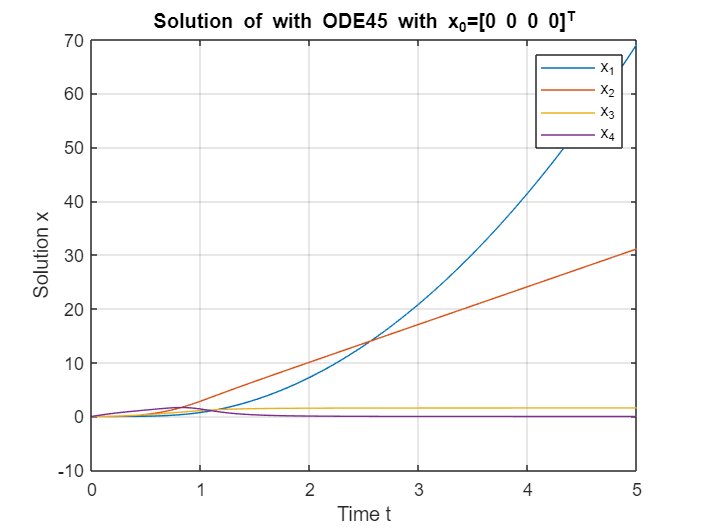

tspan = [0 5];
[time,x] = ode45(@(t,x) odefcn(t,x),tspan,[0 0 0 0]);
figure(1)
plot(time, x)
title('Solution of with ODE45 with x_0=[0 0 0 0]^T');
xlabel('Time t');
ylabel('Solution x');
legend('x_1','x_2', 'x_3', 'x_4')
grid on

## 2

Ja = jacobian([x1dot, eq_x2dot, x3dot, eq_x4dot], [x1, x2, x3, x4]);
A = subs(Ja, {x1, x2, x3, x4, u}, {0, 0, 0, 0, 0});
A_matrix = vpa(A)

$$A\_matrix = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -0.37800231194074585511603465092137 & 0 & 7.0147371686269233059274629246388 & 0.034265245251245169257884969866811\\ 0 & 0 & 0 & 1.0\\ 18.900115597037290752313968305761 & 0 & -0.37971557420330811326463544522379 & -1.7132622625622582812816037264368 \end{array}\right)$$

Jb = jacobian([x1dot, eq_x2dot, x3dot, eq_x4dot], u);
B = subs(Jb, {x1, x2, x3, x4, u}, {0, 0, 0, 0, 0});
B_matrix = vpa(B)

$$B\_matrix = \left(\begin{array}{c} 0\\ -0.069929071941316671954867285442471\\ 0\\ 3.4964535970658332271053137274221 \end{array}\right)$$


Xdot_linearized = A*[x1; x2; x3; x4] + B*u

$$Xdot\_linearized = \left(\begin{array}{c} x_{2}\\ \frac{365878782679085141984255893552369959049833\,x_{3}}{52158587539881110460908241449080132975145}-\frac{3943213335527767891263919156667351040000\,x_{1}}{10431717507976222092181648289816026595029}-\frac{729480324086761908377438134468608000000\,u}{10431717507976222092181648289816026595029}+\frac{357445358802513335104944685889617920000\,x_{4}}{10431717507976222092181648289816026595029}\\ x_{4}\\ \frac{36474016204338091552480465734092655165440\,u}{10431717507976222092181648289816026595029}+\frac{985803333881941868316887852958073629966336\,x_{1}}{52158587539881110460908241449080132975145}-\frac{3961085603467893554740545862236110848000\,x_{3}}{10431717507976222092181648289816026595029}-\frac{89361339700628324303577141048527005155328\,x_{4}}{52158587539881110460908241449080132975145} \end{array}\right)$$

Xdot = vpa(Xdot_linearized)

$$Xdot = \left(\begin{array}{c} x_{2}\\ 7.0147371686269233059274629246388\,x_{3}-0.37800231194074585511603465092137\,x_{1}-0.069929071941316671954867285442471\,u+0.034265245251245169257884969866811\,x_{4}\\ x_{4}\\ 3.4964535970658332271053137274221\,u+18.900115597037290752313968305761\,x_{1}-0.37971557420330811326463544522379\,x_{3}-1.7132622625622582812816037264368\,x_{4} \end{array}\right)$$

## 4

c = [1 0 0 0; 0 0 1 0];
C = [B A*B (A^2)*B (A^3)*B];
O = [c; c*A; c*(A^2); c*(A^3)];
Controllability = vpa(C)

$$Controllability = \left(\begin{array}{cccc} 0 & -0.069929071941316671954867285442471 & 0.1198068400130591324530502194619 & 24.347875818791484585364391056035\\ -0.069929071941316671954867285442471 & 0.1198068400130591324530502194619 & 24.347875818791484585364391056035 & -41.80507659944788982676949732441\\ 0 & 3.4964535970658332271053137274221 & -5.990342000652955987652325905215 & 7.6137014609909112783808045136689\\ 3.4964535970658332271053137274221 & -5.990342000652955987652325905215 & 7.6137014609909112783808045136689 & -8.5052781135161591481215704197025 \end{array}\right)$$

Observability = vpa(O)

$$Observability = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 1.0 & 0 & 0\\ 0 & 0 & 0 & 1.0\\ -0.37800231194074585511603465092137 & 0 & 7.0147371686269233059274629246388 & 0.034265245251245169257884969866811\\ 18.900115597037290752313968305761 & 0 & -0.37971557420330811326463544522379 & -1.7132622625622582812816037264368\\ 0.6476170962093667839354981965076 & -0.37800231194074585511603465092137 & -0.013011047275793736022065610053901 & 6.9560318170205243310254683171025\\ -32.380854810468335764274929847231 & 18.900115597037290752313968305761 & 0.65055236378968673214213081244878 & 2.5555520061166403206850042483316 \end{array}\right)$$

## 5

syms t;
[Q,J] = jordan(A);
e_j = expm(J*t);
phi = Q * e_j * inv(Q);
Phi(t) = vpa(phi)

## 6

s = tf('s');
A = double(A);
B = double(B);
sys = ss(A, B, c, 0);
G_s = tf(sys)

G_s =
 
  From input to output...
               -0.06993 s^2 + 9.938e-16 s + 24.5
   1:  --------------------------------------------------
       s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
                     3.496 s^2 - 2.747e-16
   2:  --------------------------------------------------
       s^4 + 1.713 s^3 + 0.7577 s^2 + 7.105e-15 s - 132.4
 
Continuous-time transfer function.



## 8


A_c = [0 1 0; 0 0 1; -44.29 -14.82 -4.702];
B_c = [0; 0; 1]

B_c =      0
     0
     1


C_c = [24.5 -0.06993 0]

C_c =    24.5000   -0.0699         0



C_controllability = [B_c A_c*B_c (A_c^2)*B_c];
Controllability_Compensated = vpa(C_controllability)

$$Controllability\_Compensated = \left(\begin{array}{ccc} 0 & 0 & 1.0\\ 0 & 1.0 & -4.702\\ 1.0 & -4.702 & 7.2888039999999989504431141540408 \end{array}\right)$$

rank(Controllability_Compensated)

ans = 3

function xdot = odefcn(t,x)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    x4 = x(4);
    u = zeros(size(t));
    u(t >= 0) = 1;

    xdot = zeros(4,1);
    xdot(1) = x2;
    xdot(2) = (71778311772385457136805581255138607104000*x1^3*x4^2 + 704145238487101334512062752112909735690240*sin(x3)*x1^2 + 37296329811650471908024340234577431756800*x1*x4^2 + 4019585459253586025753230536867840000000*x2*x1*x4 - 19716066677638839456319595783336755200000*cos(x3)*x1 + 1787226794012566675524723429448089600000*x4 + 1787226794012566537115851165353515625*x3 + 365876995452291129417718777701204605534208*sin(x3) - 3647401620433809541887190672343040000000*u*cos(x3))/(5*(20097927296267927998305562751438809989120*x1^2 + 10431717507976222092181648289816026595029));
    xdot(3) = x4;
    xdot(4) = -(1152921504606846976*(77508606911709102500*x3 + 77508606911709108502528*x4 + 17100961859812073090625*sin(x3) + 1743217314965552812500*x1*x4^2 - 158180830432059405107200*u*cos(x3) - 855048092990603563892736*x1*cos(x3) + 174321731496555262771200*x1*x2*x4))/(5*(20097927296267927998305562751438809989120*x1^2 + 10431717507976222092181648289816026595029));
end
